# Center a molecule

Import a structure and center it

close all;
atom=import_atom('6x4MMT_x10y5z0.gro'); % A non-centered structure

Found .gro file
.gro file imported
Elapsed time is 0.036165 seconds.
Looking up bonds
Calculating the distance matrix


i = 960

ans = 1×1 cell array
    {'Al'}

ans = 1×1 cell array
    {'H'}

ans = 1×1 cell array
    {'O'}

ans = 1×1 cell array
    {'Si'}

Looking for neighbours/bonds
Composition info:


composition = struct with fields:
     resnames: {'MMT'}
    nresidues: 1
       natoms: 960

Atom_types = 1×4 cell array
    {'Al'}    {'H'}    {'O'}    {'Si'}

Atom_numbers =     96    96   576   192


The box dimensions are:


Box_dim =    31.1880   36.0600   10.0000


The cell dimensions are:


Cell =    31.1880   36.0600   10.0000   90.0000   90.0000   90.0000


Molecular weight in g/mol, Mw:


Mw = 1.7295e+04

Molecular weight in g/mol, considering Mw_occupancy:


Mw_occupancy = 1.7295e+04

Volume in Å^3:


Box_volume = 1.1246e+04

Density in g/cm^3


Box_density = 2.5537

atom=center_atom(atom,Box_dim); % This will also replicate Box_dim

Centering
centering along x
centering along y
centering along z


ans = -0.0050

Choose between these representations:
ballstick licorice smallvdw halfvdw vdw crystal ionic polyhedra lines labels index


rmaxlong = 2.2500

Scanning intramolecular bonds, neglecting the PBC
Calculating the distance matrix


i = 960

ans = 1×1 cell array
    {'Al'}

ans = 1×1 cell array
    {'H'}

ans = 1×1 cell array
    {'O'}

ans = 1×1 cell array
    {'Si'}

Looking for neighbours/bonds


Elapsed time is 0.435381 seconds.
Drawing the atoms


Elapsed time is 1.319199 seconds.
Drawing the bonds


ans = 100

ans = 200

ans = 300

ans = 400

ans = 500

ans = 600

ans = 700

ans = 800

ans = 900

ans = 1000

ans = 1100

ans = 1200

ans = 1300

Elapsed time is 3.560331 seconds.


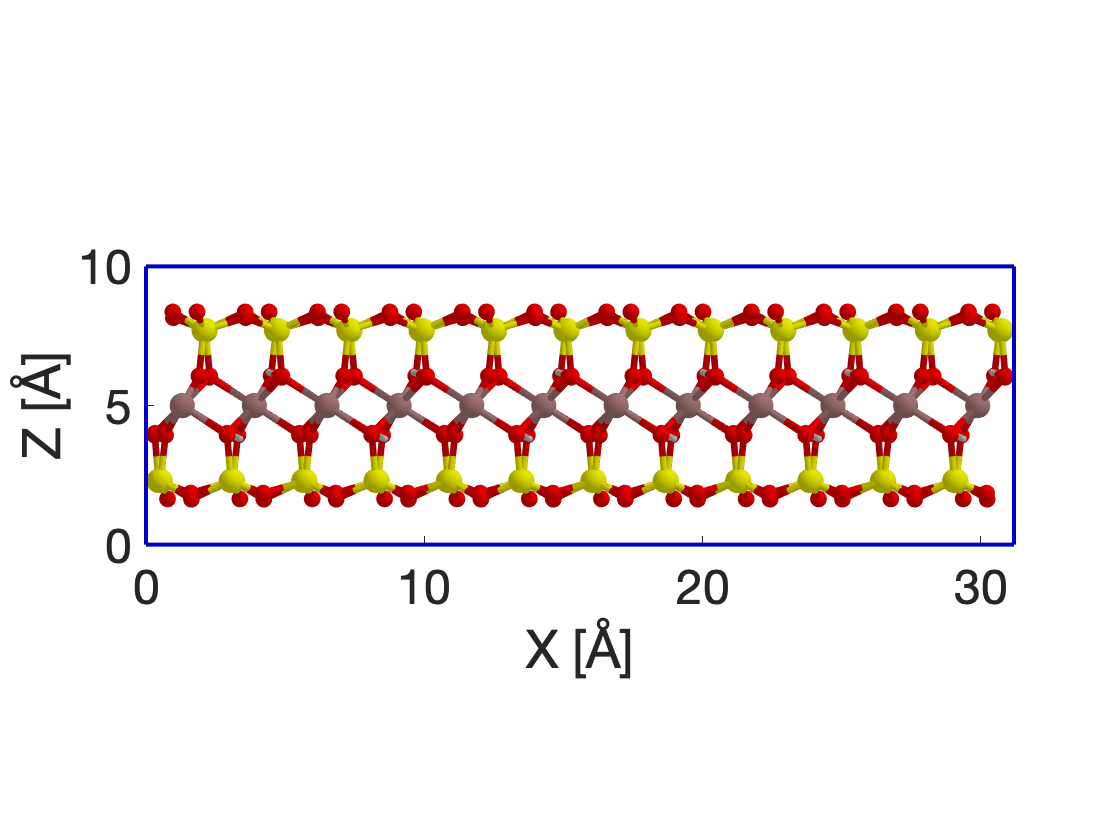

show_atom(atom,Box_dim,.1,1);

%vmd(atom,Box_dim)

We can also center with respect to a certain resname group (here `'MMT'`)

close all;
atom=import_atom('6x4MMT_x10y5z0.gro');
atom=center_atom(atom,Box_dim,'MMT'); % Default 'all'
show_atom(atom,Box_dim,.1,1);
%vmd(atom,Box_dim)

Or we can center with respect a certain x, y or z direction (here in the `'z'` direction)

close all;
atom=import_atom('6x4MMT_x10y5z0.gro');
atom=center_atom(atom,Box_dim,'MMT','z'); % Default 'xyz'
show_atom(atom,Box_dim,.1,1);
%vmd(atom,Box_dim)